# Hypothesis testing

clc;
close all;
clear variables;

set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

## Parameters

ma = [3; -4]; 
mb = [10; -4];

sigma_a = [1.7; 3];
sigma_b = [3; 1.4];


rho_a = 0.6;
rho_b = 0.7;

num_a = 5000;
num_b = 5000;

## Samples

A = Samples(ma, sigma_a, rho_a,  num_a);
B = Samples(mb, sigma_b, rho_b, num_b);

### Plotting

syms x_1 x_2 real
X = [x_1; x_2];

line_width = 3;

% plotting samples
figure();
grid on; hold on; axis equal;
labels = {};

A.plot('b.'); labels{end+1} = 'A';
B.plot('r.'); labels{end+1} = 'B';

title('Samples with constant pdf countours');
xlabel('$x_1$')
ylabel('$x_2$')


$$f(X) = const$$


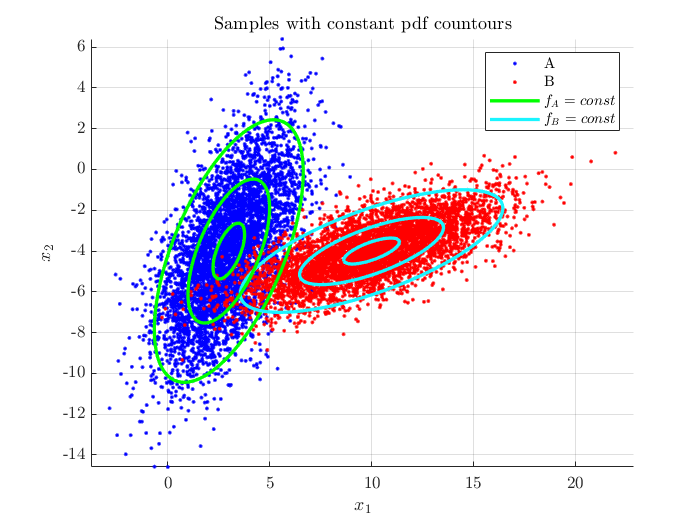

% plotting the constant pdf curves
for const_pdf_val = [0.1 0.5 0.9]
    fimplicit(exp(-0.5 * (X - A.M)' * A.cov_mat ^ (-1) * (X - A.M)) == const_pdf_val, 'Color', '#00ff00', 'LineWidth', 2)
    fimplicit(exp(-0.5 * (X - B.M)' * B.cov_mat ^ (-1) * (X - B.M)) == const_pdf_val, 'Color', '#1AF4FF', 'LineWidth', 2)
end

labels{end+1} = '$f_A = const$';
labels{end+1} = '$f_B = const$';
legend(labels);

% plotting samples
figure();
grid on; hold on; axis equal;
labels = {};

A.plot('b.'); labels{end+1} = 'A';
B.plot('r.'); labels{end+1} = 'B';

title("Samples and the discrimination line - Bayes' test");
xlabel('$x_1$')
ylabel('$x_2$')

## Bayes' test of least error


$$h(X) = -ln\left(\frac{f_1}{f_2}\right) <> ln\left(\frac{P_1}{P_2}\right)$$


P = [A.num / (A.num + B.num); 
    B.num / (A.num + B.num)];

threshold = log(P(1) / P(2));
h = -log(A.pdf_sym(X) / B.pdf_sym(X));

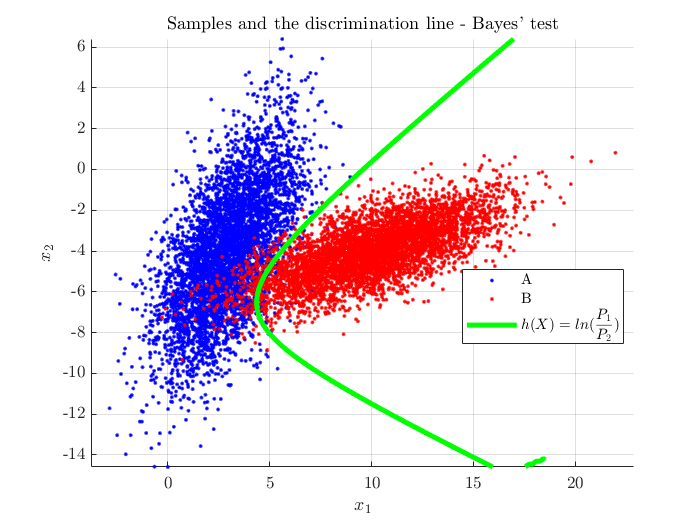

% plotting the discrimination line
fimplicit(h == threshold, 'Color', 'g', 'LineWidth', line_width)
labels{end+1} = '$h(X) = ln(\displaystyle\frac{P_1}{P_2})$';

legend(labels, "Location","best");

### Error estimation

#### Histogram

h_a = A.discrimination_function(B, 1);
h_b = B.discrimination_function(A, 2);

n_bins = 40;
distribution_name = 'kernel';

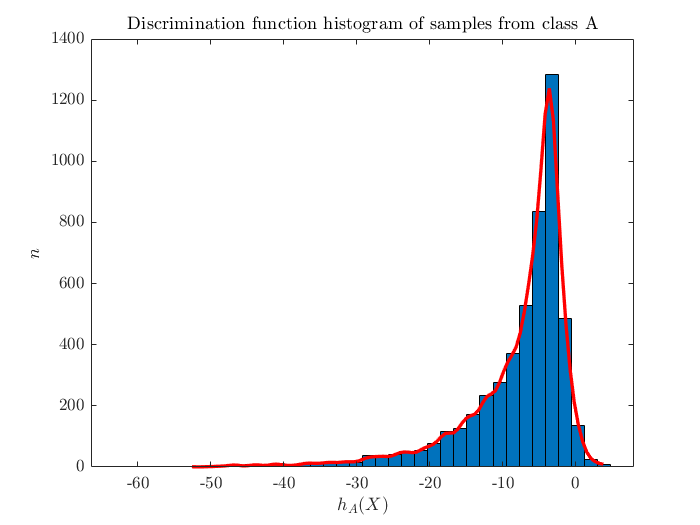

% plotting histogram for class 1 (A)
figure();
histfit(h_a, n_bins, distribution_name);
title('Discrimination function histogram of samples from class A')
xlabel('$h_A(X)$')
ylabel('$n$')

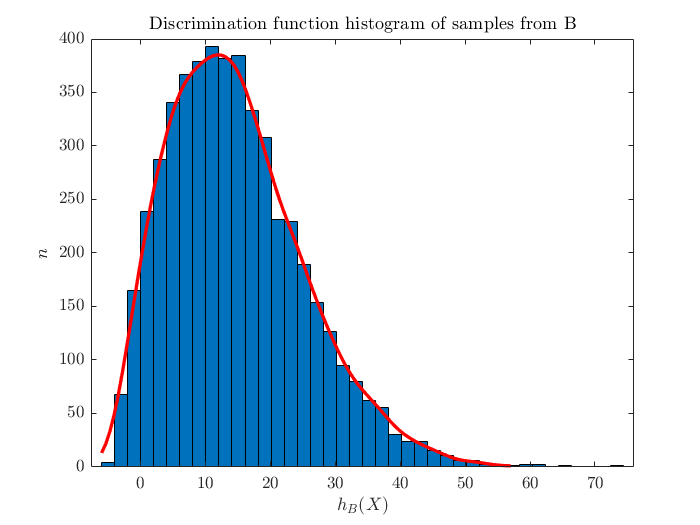

% plotting histogram for class 2 (B)
figure();
histfit(h_b, n_bins, distribution_name);
title('Discrimination function histogram of samples from B')
xlabel('$h_B(X)$')
ylabel('$n$')

#### PDF approximation

x_a = (-110:0.001:110)';
x_b = x_a;

[y_a, fitobject_a] = approximate_pdf(h_a, x_a);
[y_b, fitobject_b] = approximate_pdf(h_b, x_b);

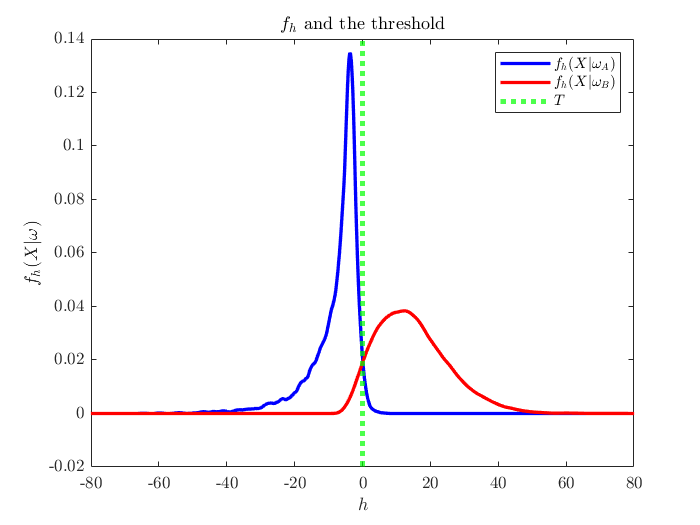

% plotting the estimated pdfs
figure();
plot(fitobject_a, 'b');
hold on;
plot(fitobject_b, 'r');

xline(threshold, 'g:', 'LineWidth', 3)
xlim([-80, 80])

set(findall(gca, 'Type', 'Line'),'LineWidth', 2);

title("$f_h$ and the threshold")
xlabel("$h$")
ylabel("$f_h(X|\omega)$")
legend('$f_h(X|\omega_A)$', '$f_h(X|\omega_B)$', '$T$')

#### Error estimates

h_eps_1 = integrate(fitobject_a, max(x_a), threshold);
h_eps_2 = integrate(fitobject_b, threshold, min(x_b));

freqentist_eps_1 = length(h_a(h_a > threshold)) / length(h_a);
freqentist_eps_2 = length(h_b(h_b < threshold)) / length(h_b);

error_approx_table = table(h_eps_1, h_eps_2, freqentist_eps_1, freqentist_eps_2)

error_approx_table = 1×4 table
    h_eps_1     h_eps_2     freqentist_eps_1    freqentist_eps_2
    ________    ________    ________________    ________________

    0.025085    0.053932         0.0208              0.047      


total_error_h = h_eps_1 * P(1) + h_eps_2 * P(2);
total_error_freq = freqentist_eps_1 * P(1) + freqentist_eps_2 * P(2);

total_error_table = table(total_error_h, total_error_freq)

total_error_table = 1×2 table
    total_error_h    total_error_freq
    _____________    ________________

      0.039509            0.0339     


## Min-max test

P1_range = 0.0:0.01:1;
risk = zeros(length(P1_range), 1);

for i = 1:length(P1_range)
    
    P2 = 1 - P1_range(i);
    threshold = log(P1_range(i) / P2);
    
    h_eps_1 = integrate(fitobject_a, max(x_a), threshold);
    h_eps_2 = integrate(fitobject_b, threshold, min(x_b));
    
    risk(i) = P1_range(i) * h_eps_1 + P2 * h_eps_2;   
end

### Optimal risk

[max_risk, argmax] = max(risk);
P1_max_risk = P1_range(argmax);

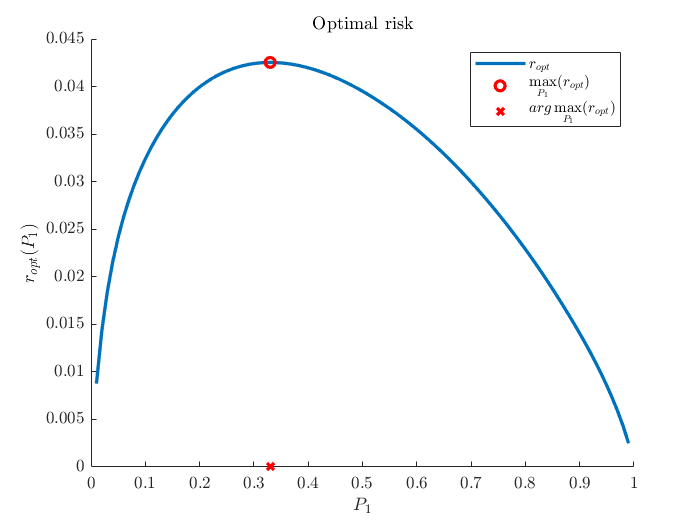

% plotting optimal risk
figure();
hold on;

plot(P1_range, risk);
plot(P1_max_risk, max_risk, 'ro')
plot(P1_max_risk, 0, 'rx')

set(findall(gca, 'Type', 'Line'),'LineWidth', 2);

title("Optimal risk")
xlabel("$P_1$")
ylabel("$r_{opt} (P_1)$")
legend("$r_{opt}$", "$\max\limits_{P_1}(r_{opt})$", "$ arg\max \limits_{P_1}(r_{opt})$")

### Min-max test classifier

% plotting samples
figure();
grid on; hold on; axis equal;
labels = {};

A.plot('b.'); labels{end+1} = 'A';
B.plot('r.'); labels{end+1} = 'B';

title('Samples and the discrimination line - Min-max test');
xlabel('$x_1$')
ylabel('$x_2$')

threshold = log(P1_max_risk / (1 - P1_max_risk));
h = -log(A.pdf_sym(X) / B.pdf_sym(X));

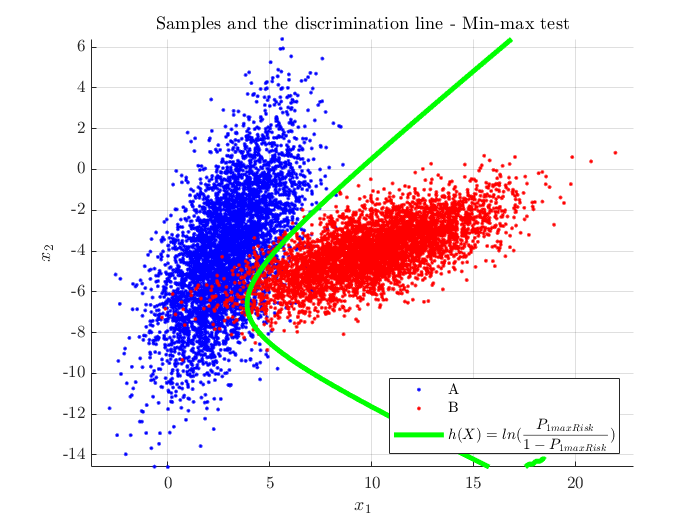

% plotting the discrimination line
fimplicit(h == threshold, 'Color', 'g', 'LineWidth', line_width)

labels{end+1} = '$h(X) = ln(\displaystyle\frac{P_{1 maxRisk}}{1 - P_{1 maxRisk}})$';
legend(labels, "Location","southeast");

### Error estimates

h_eps_1 = integrate(fitobject_a, max(x_a), threshold);
h_eps_2 = integrate(fitobject_b, threshold, min(x_b));

freqentist_eps_1 = length(h_a(h_a > threshold)) / length(h_a);
freqentist_eps_2 = length(h_b(h_b < threshold)) / length(h_b);

error_approx_table = table(h_eps_1, h_eps_2, freqentist_eps_1, freqentist_eps_2)

error_approx_table = 1×4 table
    h_eps_1     h_eps_2     freqentist_eps_1    freqentist_eps_2
    ________    ________    ________________    ________________

    0.044773    0.041432         0.039               0.0334     


total_error_h = h_eps_1 * P(1) + h_eps_2 * P(2);
total_error_freq = freqentist_eps_1 * P(1) + freqentist_eps_2 * P(2);

total_error_table = table(total_error_h, total_error_freq)

total_error_table = 1×2 table
    total_error_h    total_error_freq
    _____________    ________________

      0.043103            0.0362     


### Comparison of Min-max and Bayes

% plotting samples
figure();
grid on; hold on; axis equal;
labels = {};

A.plot('b.'); labels{end+1} = 'A';
B.plot('r.'); labels{end+1} = 'B';

title('Samples and the discrimination line - Min-max test');
xlabel('$x_1$')
ylabel('$x_2$')

threshold = log(P1_max_risk / (1 - P1_max_risk));
h = -log(A.pdf_sym(X) / B.pdf_sym(X));

% plotting min-max discrimation line
fimplicit(h == threshold, 'Color', 'g', 'LineWidth', line_width)
labels{end+1} = '$h(X) = ln(\displaystyle\frac{P_{1 maxRisk}}{1 - P_{1 maxRisk}})$';

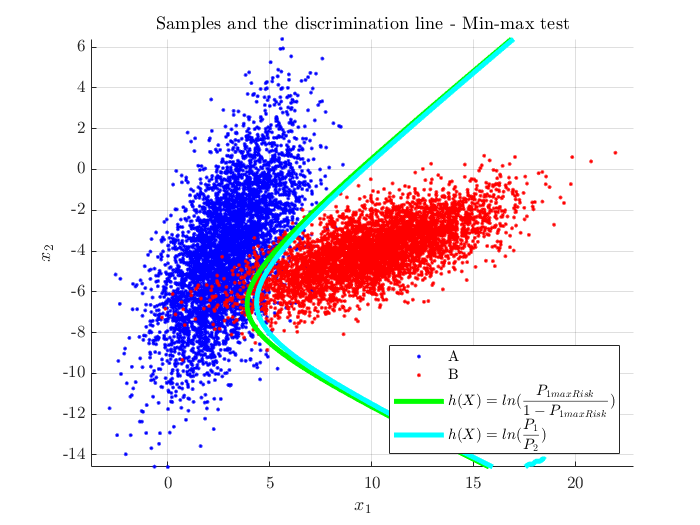

% plotting bayes' discrimination line
fimplicit(h == log(P(1) / P(2)), 'Color', 'c', 'LineWidth', line_width)
labels{end+1} = '$h(X) = ln(\displaystyle\frac{P_1}{P_2})$';

legend(labels, "Location","southeast");

% TODO mozda novi uzorci sa drugim P1 P2 pa kao da se vidi da je isti rizik

## Wald's sequential hypothesis test

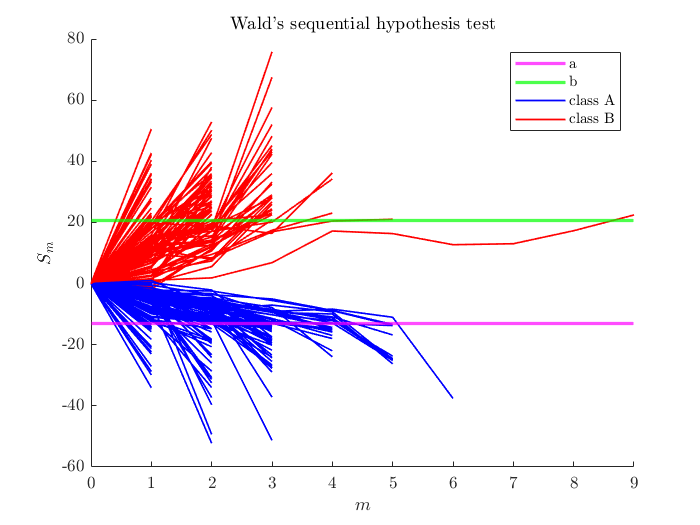

eps_1 = 1e-9;
eps_2 = 2e-6;

[limit_a, limit_b] = wald_limits(eps_1, eps_2);

N = 100;

m_a_array = zeros(N, 1);
m_b_array = zeros(N, 1);

figure();
hold on;

yline(limit_a, 'm', "LineWidth", 2)
yline(limit_b, 'g', "LineWidth", 2)

for i = 1:N
    sample_A = Samples(ma, sigma_a, rho_a,  1);
    sample_B = Samples(mb, sigma_b, rho_b, 1);
    
    [sm_array_a, m_a_array(i)] = walds_sequential_test(A, eps_1, eps_2, B, 1);
    [sm_array_b, m_b_array(i)] = walds_sequential_test(B, eps_1, eps_2, A, 2);
    
    plot(0:m_a_array(i), sm_array_a, 'b')
    plot(0:m_b_array(i), sm_array_b, 'r')  
end

set(findall(gca, 'Type', 'Line'),'LineWidth', 1);


title("Wald's sequential hypothesis test")
xlabel("$m$")
ylabel("$S_m$")
legend("a", "b","class A", "class B")

m_A_mean = mean(m_a_array);
m_B_mean = mean(m_b_array);
mean_and_error_table = table(eps_1, eps_2,m_A_mean, m_B_mean)

mean_and_error_table = 1×4 table
    eps_1    eps_2    m_A_mean    m_B_mean
    _____    _____    ________    ________

    1e-09    2e-06      2.69        2.21  


num_eps = 200;
eps_1 = 1e-9;
eps_2 = 2e-6;

% eps_1_array = logspace(-9, 0, num_eps);
eps_1_array = linspace(1e-9,1, num_eps);
m_mean = zeros(num_eps, 1);
for j = 1:num_eps
    eps_1 = eps_1_array(j);
    for i = 1:N
        sample_A = Samples(ma, sigma_a, rho_a,  1);
        sample_B = Samples(mb, sigma_b, rho_b, 1);
        
        [~, m_a_array(i)] = walds_sequential_test(A, eps_1, eps_2, B, 1);
        [~, m_b_array(i)] = walds_sequential_test(B, eps_1, eps_2, A, 2);
    end
    m_mean(j) = mean(m_a_array);
end

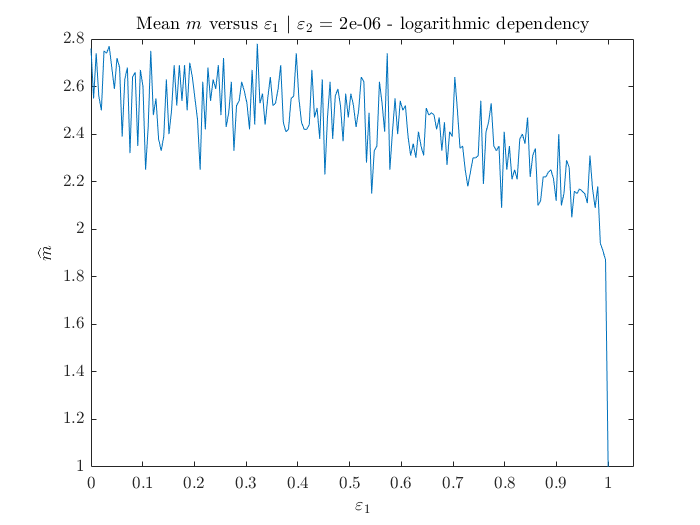


figure();
plot(eps_1_array, m_mean)

xlim([0, 1.05])

title("Mean $m$ versus $\varepsilon_1 \  | \  \varepsilon_2$ = " + eps_2 + " - logarithmic dependency")
xlabel("$\varepsilon_1$")
ylabel("$\widehat{m}$")

% TODO Isto za epsilon_2